# **Interpolação**

**Forma de Newton**

Dados $n+1$ pontos $(x_{0}, f(x_{0}) ), (x_{1}, f(x_{1}) ), \dots, (x_{n},f(x_{n}))$


$$p_n(x)=d_{0} + d_{1}(x-x_{0})+d_{2}(x-x_{0})(x-x_{1})+\cdots+d_{n}(x-x_{0})(x-x_{1})\dots(x-x_{n-1})$$


**Exercício 1:** Encontre o polinômio de grau $\leq$ 2 que interpola os pontos (-1,4),(0,1), (2,-1).

Implementação :

clear
%Encontrar o polinômio interpolador pela Forma de Newton
x = [ -1; 0; 2];
y = [4; 1; -1];
n = length(x);

%1 -  Criação da tabela de diferenças divididas
dd(:,1) = y;
for i = 2:n
    for j = 2:i
        dd(i,j) = ( dd(i,j-1) - dd(i-1,j-1) ) / ( x(i) - x(i-j+1) );
    end
end
dd

dd =     4.0000         0         0
    1.0000   -3.0000         0
   -1.0000   -1.0000    0.6667


%2 - Escrever o polinômio na forma de Newton p2(x) = d0 + d1(x-x0) + d2(x-x0)(x-x1)
syms X

p2 = dd(1,1) + dd(2,2)*(X-x(1)) + dd(3,3)*(X-x(1))*(X-x(2))

$$p2 = X\,\left(\frac{2\,X}{3}+\frac{2}{3}\right)-3\,X+1$$

expand(p2)

$$ans = \frac{2\,X^{2}}{3}-\frac{7\,X}{3}+1$$

simplify(p2, "Steps", 500)

$$ans = \frac{\left(2\,X-1\right)\,\left(X-3\right)}{3}$$

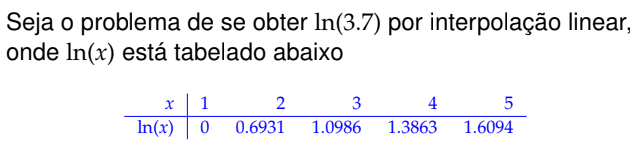

% interpolação linear
x = [3;4];
y = [1.0986;1.3863];

n = length(x);
dd(:,1) = y;
for i = 2:n
    for j = 2:i
        dd(i,j) = ( dd(i,j-1) - dd(i-1,j-1) ) / ( x(i) - x(i-j+1) );
    end
end
dd

dd =     1.0986         0
    1.3863    0.2877


syms X
p1 = dd(1,1)+dd(2,2)*(X-x(1))

$$p1 = \frac{2877\,X}{10000}+\frac{471}{2000}$$

p1_resolucao = dd(1,1)+dd(2,2)*(3.7-x(1))

p1_resolucao = 1.3000

E1 = log(3.7)-p1_resolucao

E1 = 0.0083

E1_x = (3.7-x(1))*(3.7-x(2))*((-1/(3.7)^2)/2)

E1_x = 0.0077

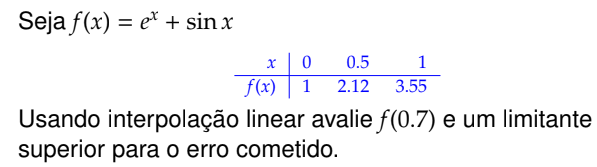

x = [0;1];
y = [1;3.55];
p1 = polyfit(x,y,1)

p1 =     2.5500    1.0000


polyval(p1,0.7)

ans = 2.7850

f2 = exp(1)-sin(1)

f2 = 1.8768

% corolário 2
E1 = (1^2 * f2)/(4*(1+1))

E1 = 0.2346

% interpolação entre 0.5 e 1
x1 = [0.5;1];
y = [2.12;3.55];
p1_1 = polyfit(x,y,1)

p1_1 =     1.4300    2.1200


polyval1 = polyval(p1_1,0.7)

polyval1 = 3.1210

E_1 = (0.5^2 * f2)/(4*(1+1))

E_1 = 0.0587

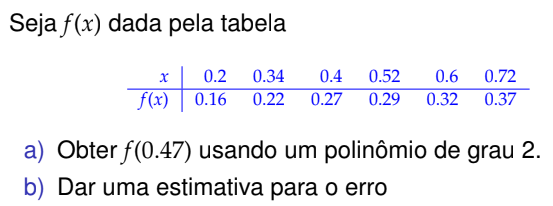

x = [0.2;0.34;0.4;0.52;0.6;0.72];
y = [0.16;0.22;0.27;0.29;0.32;0.37];

n = length(x);
dd(:,1) = y;
for i = 2:n
    for j = 2:i
        dd(i,j) = ( dd(i,j-1) - dd(i-1,j-1) ) / ( x(i) - x(i-j+1) );
    end
end
dd

dd =     0.1600         0         0         0         0         0
    0.2200    0.4286         0         0         0         0
    0.2700    0.8333    2.0238         0         0         0
    0.2900    0.1667   -3.7037  -17.8985         0         0
    0.3200    0.3750    1.0417   18.2514   90.3748         0
    0.3700    0.4167    0.2083   -2.6042  -54.8831 -279.3421


x1 = [0.4;0.52;0.6];
y1 = [0.27;0.29;0.32];

p2 = polyfit(x1,y1,2)

p2 =     1.0417   -0.7917    0.4200


p2_2 = polyval(p2,0.47)

p2_2 = 0.2780

E247 = abs((0.47-x1(1))*(0.47-x1(2))*(0.47-x1(3)))*(norm(dd(:,4), inf))

E247 = 0.0083